# Explore the dynamics of a 4-dof Robotic manipulator

In this example we're going to define the model parameters for a 4-dof robotic manipulator.  The system that we're going to explore is shown below:

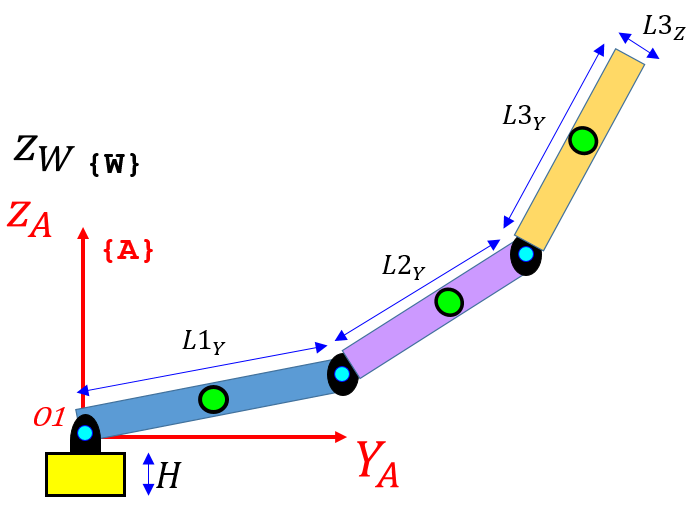   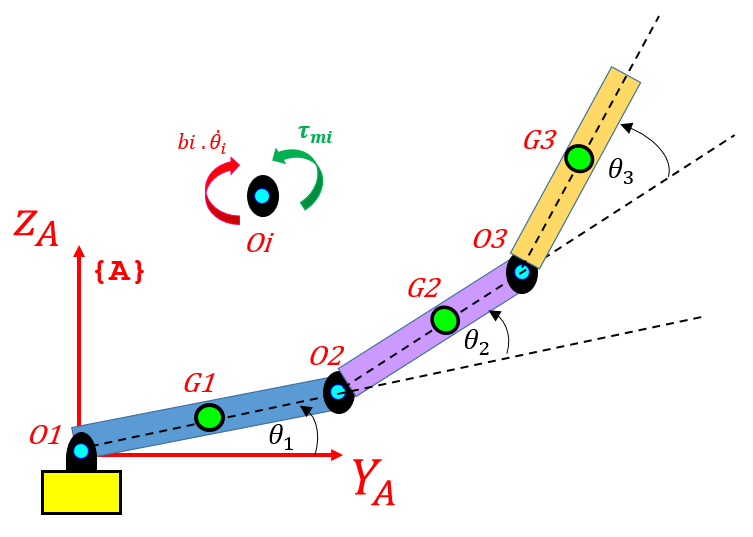   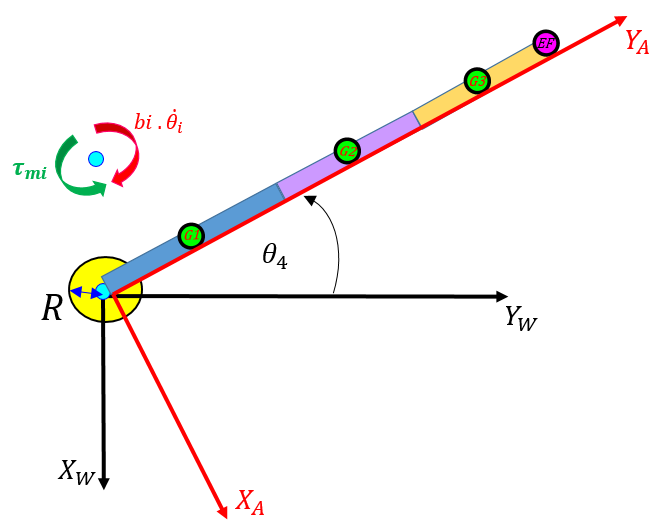

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`

## Define some model parameters for our manipulator:

We'll represent each link in the pendulum as a rectangular prism(or BRICK).  So one of the first things we'll need are the inertia properties of the 3 links. We'll assume that each link has the same density.

density = 1000; % kg/m3

## Define some geometry parameters for our Turntable:

Hz     = 0.20;  % m
Rturn  = 0.05;  % m  
mass4  = density * Hz*pi*(Rturn^2); % kg

## Define some geometry parameters for our LINKS:

L1y     = 0.75; % m
L1z     = 0.050; % m
L1x     = 0.005; % m
mass1   = density * L1x*L1y*L1z; % kg

## Define some geometry parameters for LINK 2:

L2y     = 0.50; % m
L2z     = 0.05; % m
L2x     = 0.005; % m
mass2   = density * L2x*L2y*L2z; % kg

## Define some geometry parameters for LINK 3:

L3y     = 0.25; % m
L3z     = 0.05; % m
L3x     = 0.005; % m
mass3   = density * L3x*L3y*L3z; % kg

## Define some damping at each joint:

We will assume that each pivot point experiences viscous damping, ie: $\tau_{damping} = b \thinspace \dot{\theta}$.   Note that the damping torque is a function of the relative joint velocity, eg: $\tau_2 = b_2 \thinspace . \thinspace \dot{\theta}_2$.

b1_damp = 0.005; %0.1 (N.m/(rad/sec));
b2_damp = 0.005; %0.1 (N.m/(rad/sec));
b3_damp = 0.005; %0.1 (N.m/(rad/sec));
b4_damp = 0.005; %0.1 (N.m/(rad/sec));

## Define gravity:

We'll assume that gravity acts in the negative Z-direction.

g = 9.80665;  % m/sec^2

## The System pose and INITIAL Conditions:

Here is how we'll describe the angular displacement of the 2 links.

    

Here are the system INITIAL conditions - note all units are either (rad) or (rad/sec)

- $\theta_1(0) = 0$,       `      (rad)`

- $\dot{\theta}_1(0) = 0$         `        (rad/sec)`

- $\theta_2(0) = 0$    `        (rad)`

- $\dot{\theta}_2(0) = 0$         `        (rad/sec)`

- $\theta_3(0) = 0$    `        (rad)`

- $\dot{\theta}_3(0) = 0$         `        (rad/sec)`

- $\theta_4(0) = 0$    `        (rad)`

- $\dot{\theta}_4(0) = 0$         `        (rad/sec)`

theta1_0     =  0;   % rad
theta1_dot_0 =  0;   % rad/sec 
theta2_0     =  0;   % rad
theta2_dot_0 =  0;   % rad/sec
theta3_0     =  0;   % rad
theta3_dot_0 =  0;   % rad/sec
theta4_0     =  0;   % rad
theta4_dot_0 =  0;   % rad/sec

## Some electric motor parameters:

% some DC motor parameters
P_mot.Vmax     = 12;
P_mot.ID       = 0;        % (-)           ID
P_mot.Ka       = 40e-3;    % (N.m/A)       Torque constant
P_mot.Ke       = 40e-3;    % (V.sec/rad)   Back EMF constant
P_mot.b        = [];       % (N.m.sec/rad) Viscous friction co-efficient
P_mot.I        = [];       % (kg.m^2)      Rotor ONLY Inertia
P_mot.R        = 5;        % (Ohms)        Armature resistamce
P_mot.L        = 0.63e-3;  % (Henry)       Armature Inductance
P_mot.G        = 100;      % gearbox ratio = w_in/w_out = TQ_out/TQ_in
P_mot.TQ_G_max = 3;        % (N.m)max torque from gearhead output
P_mot.TQ_m_max = P_mot.TQ_G_max/P_mot.G;% (N.m) max torque from motor shaft